%% Synthesizer Plugin Test

% add paths
addpath(genpath('test_signals'));
addpath(genpath('../effects'));
%each signal has been tested through each effect
%provided oscillator output figures for each type and 
% output after passing through WaveStorm

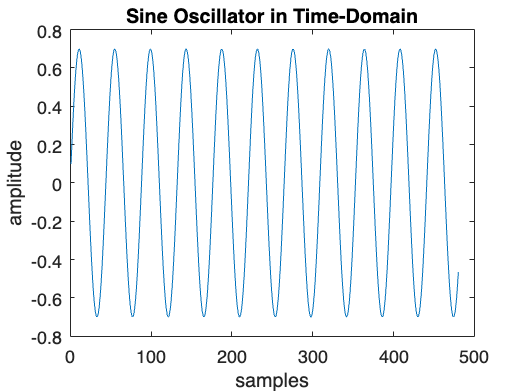

addpath(genpath('test_signals'));
addpath(genpath('../effects'));
%% sine signal 

% set buffer parameters
buff_length = 480;
fs = 48000;
test_length = 0.01;
num_buffs = round((fs*test_length)/buff_length);
osc = oscillator_class(buff_length);
osc.Fo = 1000;
sine_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [sine_signal(start_ind:end_ind),osc] = process(osc);
end



figure(1);
plot(sine_signal);
title('Sine Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

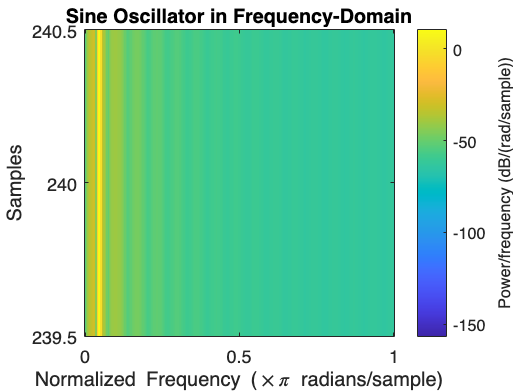



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(sine_signal, hamming(win_length), overlap_length, nfft);
title('Sine Oscillator in Frequency-Domain');

soundsc(sine_signal,fs);


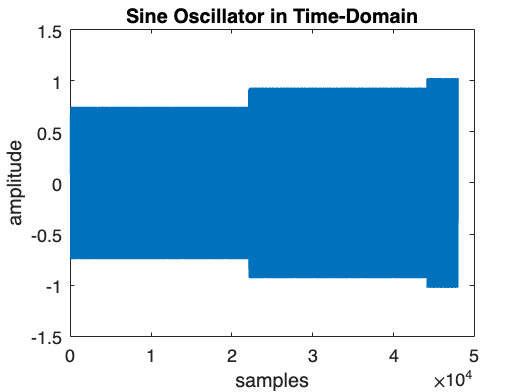


%% sine signal with effect 

% set buffer parameters
buff_length = 480;
fs = 48000;
test_length = 1.0;
num_buffs = round((fs*test_length)/buff_length);
osc = oscillator_class(buff_length);
osc.Fo = 1000;
sine_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [sine_signal(start_ind:end_ind),osc] = process(osc);
end
%passing through the effect
pluginEffect = WaveStorm();
num_buffs = floor(length(sine_signal)/buff_length);
Effect_out = zeros(size(sine_signal));
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = sine_signal(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),pluginEffect] = process(pluginEffect,buff);
end



figure(1);
plot(Effect_out);
title('Sine Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

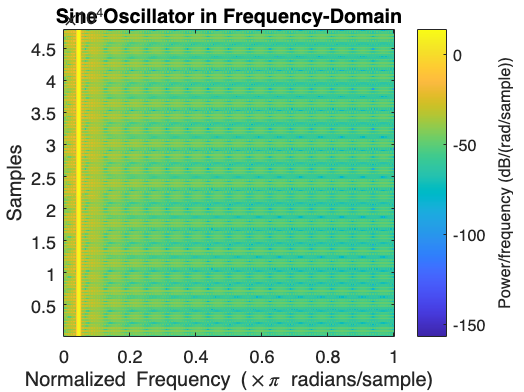



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(2);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Sine Oscillator in Frequency-Domain');

soundsc(Effect_out,fs);

%%

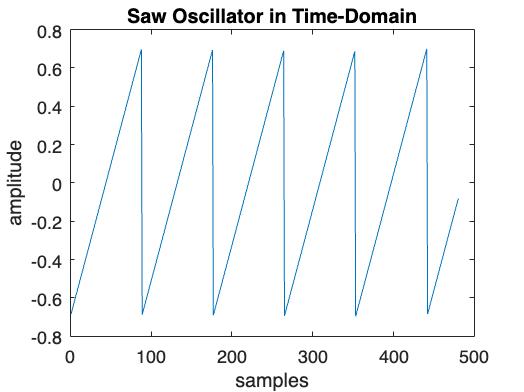

%% saw signal 
buff_length = 480;
fs = 48000;
test_length = 0.01;
num_buffs = round((fs*test_length)/buff_length);
osc = oscillator_class(buff_length);
test_length = 0.01;
osc.Type = 'Sawtooth';
saw_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [saw_signal(start_ind:end_ind),osc] = process(osc);
end


figure(3);
plot(saw_signal);
title('Saw Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

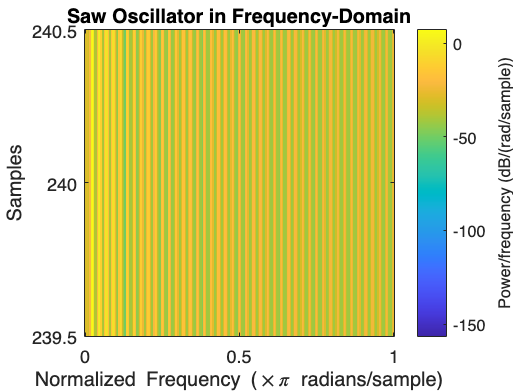



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(4);
spectrogram(saw_signal, hamming(win_length), overlap_length, nfft);
title('Saw Oscillator in Frequency-Domain');

soundsc(saw_signal,fs);

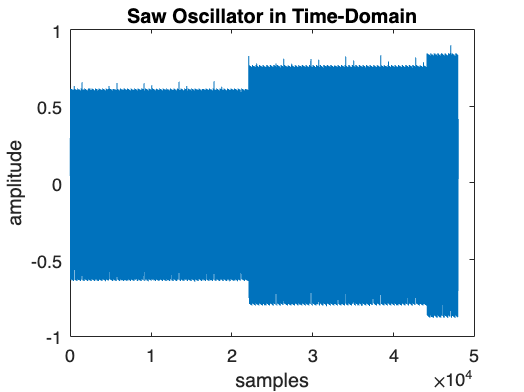

%sawtooth through wavestorm
test_length = 1.0;
osc.Type = 'Sawtooth';
saw_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [saw_signal(start_ind:end_ind),osc] = process(osc);
end
%passing through the effect
pluginEffect = WaveStorm();
num_buffs = floor(length(saw_signal)/buff_length);
Effect_out = zeros(size(saw_signal));
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = saw_signal(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),pluginEffect] = process(pluginEffect,buff);
end

figure(3);
plot(Effect_out);
title('Saw Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

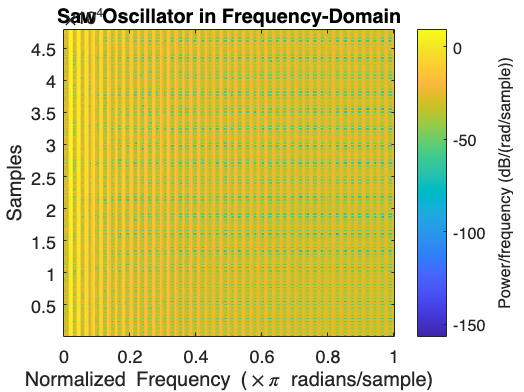



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(4);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Saw Oscillator in Frequency-Domain');

soundsc(saw_signal,fs);

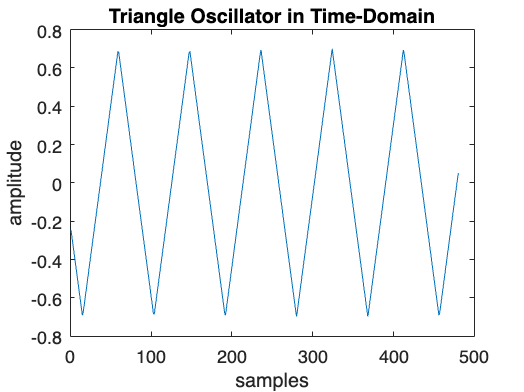

%triangle
osc.Type = 'Triangle';
triangle_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [triangle_signal(start_ind:end_ind),osc] = process(osc);
end

figure(5);
plot(triangle_signal);
title('Triangle Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

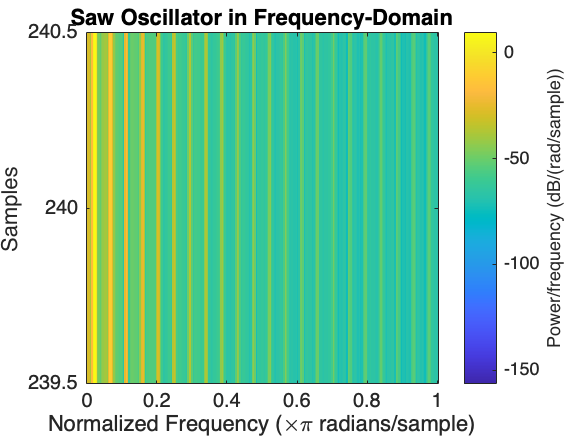



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(6);
spectrogram(triangle_signal, hamming(win_length), overlap_length, nfft);
title('Triangle Oscillator in Frequency-Domain');

soundsc(triangle_signal,fs);

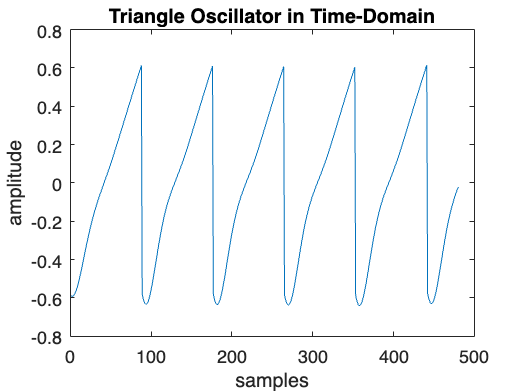

buff_length = 480;
fs = 48000;
test_length = 0.01;
num_buffs = round((fs*test_length)/buff_length);
osc = oscillator_class(buff_length);
osc.Type = 'Triangle';
triangle_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [triangle_signal(start_ind:end_ind),osc] = process(osc);
end
%passing through the effect
pluginEffect = WaveStorm();
num_buffs = floor(length(triangle_signal)/buff_length);
Effect_out = zeros(size(triangle_signal));
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = saw_signal(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),pluginEffect] = process(pluginEffect,buff);
end
figure(5);
plot(Effect_out);
title('Triangle Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

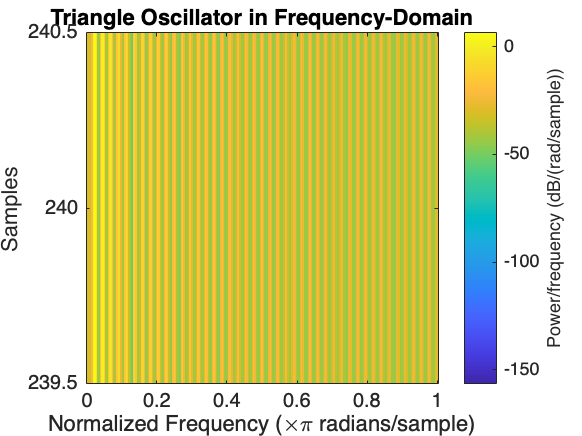



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(6);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Triangle Oscillator in Frequency-Domain');

soundsc(triangle_signal,fs);

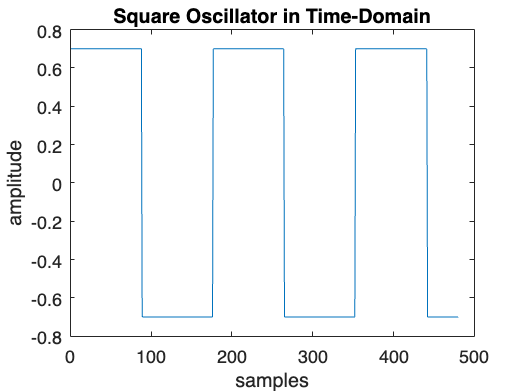

%square

buff_length = 480;
fs = 48000;
test_length = 0.01;
num_buffs = round((fs*test_length)/buff_length);
osc = oscillator_class(buff_length);
osc.Type = 'Square';
square_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [square_signal(start_ind:end_ind),osc] = process(osc);
end

figure(7);
plot(square_signal);
title('Square Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

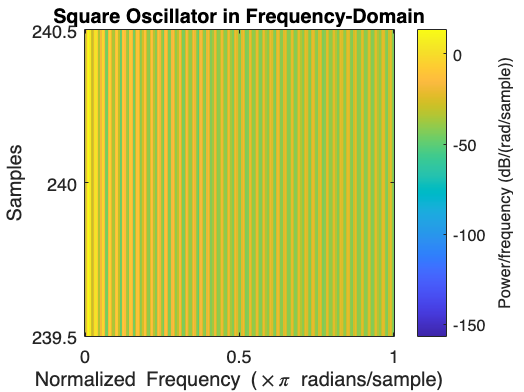



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(8);
spectrogram(square_signal, hamming(win_length), overlap_length, nfft);
title('Square Oscillator in Frequency-Domain');

soundsc(square_signal,fs);

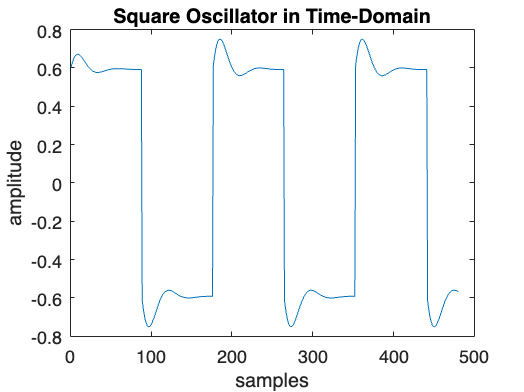

%square through wavestorm
buff_length = 480;
fs = 48000;
test_length = 0.01;
num_buffs = round((fs*test_length)/buff_length);
osc = oscillator_class(buff_length);
osc.Type = 'Square';
square_signal = zeros((test_length*fs),1);
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    [square_signal(start_ind:end_ind),osc] = process(osc);
end
%passing through the effect
pluginEffect = WaveStorm();
num_buffs = floor(length(square_signal)/buff_length);
Effect_out = zeros(size(square_signal));
for b = 1:num_buffs
    start_ind = ((b-1)*buff_length)+1;
    end_ind = start_ind + (buff_length-1);
    buff = square_signal(start_ind:end_ind);
    [Effect_out(start_ind:end_ind),pluginEffect] = process(pluginEffect,buff);
end
figure(7);
plot(Effect_out);
title('Square Oscillator in Time-Domain');
xlabel('samples');
ylabel('amplitude');

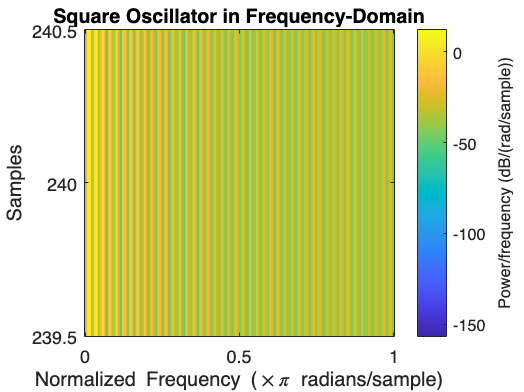



win_length = buff_length;
overlap_length = floor(win_length/2);
nfft = max(256,2^nextpow2(win_length));

figure(8);
spectrogram(Effect_out, hamming(win_length), overlap_length, nfft);
title('Square Oscillator in Frequency-Domain');

soundsc(Effect_out,fs);